Math 155 Final Project Test

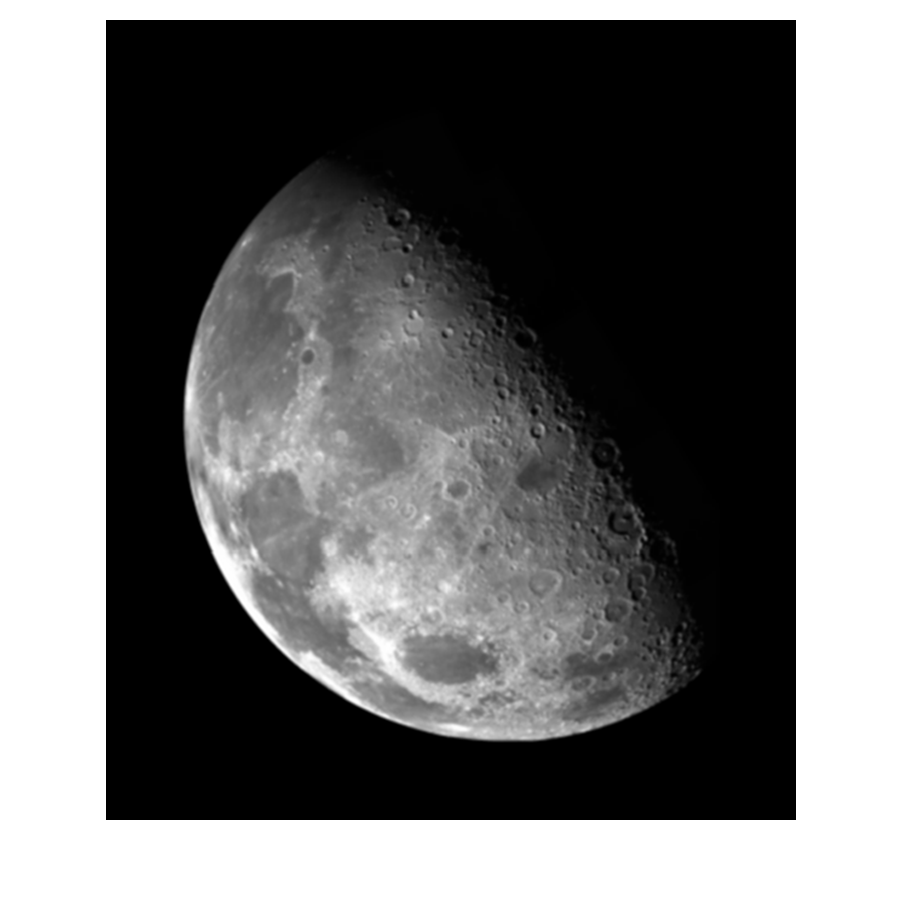

% TODO: account for color images
% TODO: use subset of images (not initial image) to construct mosaic

clear;clc;close all;
img = imread("img.tif");
imshow(img)

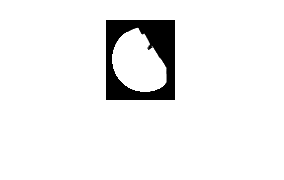

% set mosaic size scaled down from original image
scaling_factor = 10;
[img_rows, img_cols] = size(img);
mosaic_rows = floor(img_rows/scaling_factor);
mosaic_cols = floor(img_cols/scaling_factor);
total_mosaic = mosaic_rows * mosaic_cols;

% get average intensity values for regions in original image
tile_intensities = zeros(mosaic_rows,mosaic_cols);
for i = 1:mosaic_rows-1
   for j = 1:mosaic_cols-1
       tile_intensities(i,j) = mean(mean(img(i*scaling_factor:(i+1)*scaling_factor,j*scaling_factor:(j+1)*scaling_factor)));
   end
end

% construct mosaic
cell_mosaic = cell(mosaic_rows, mosaic_cols);
for i=1:mosaic_rows
    for j=1:mosaic_cols
        cell_mosaic{i,j} = tile_intensities(i,j)*img;
    end
end

% check intensities
imshow(tile_intensities)

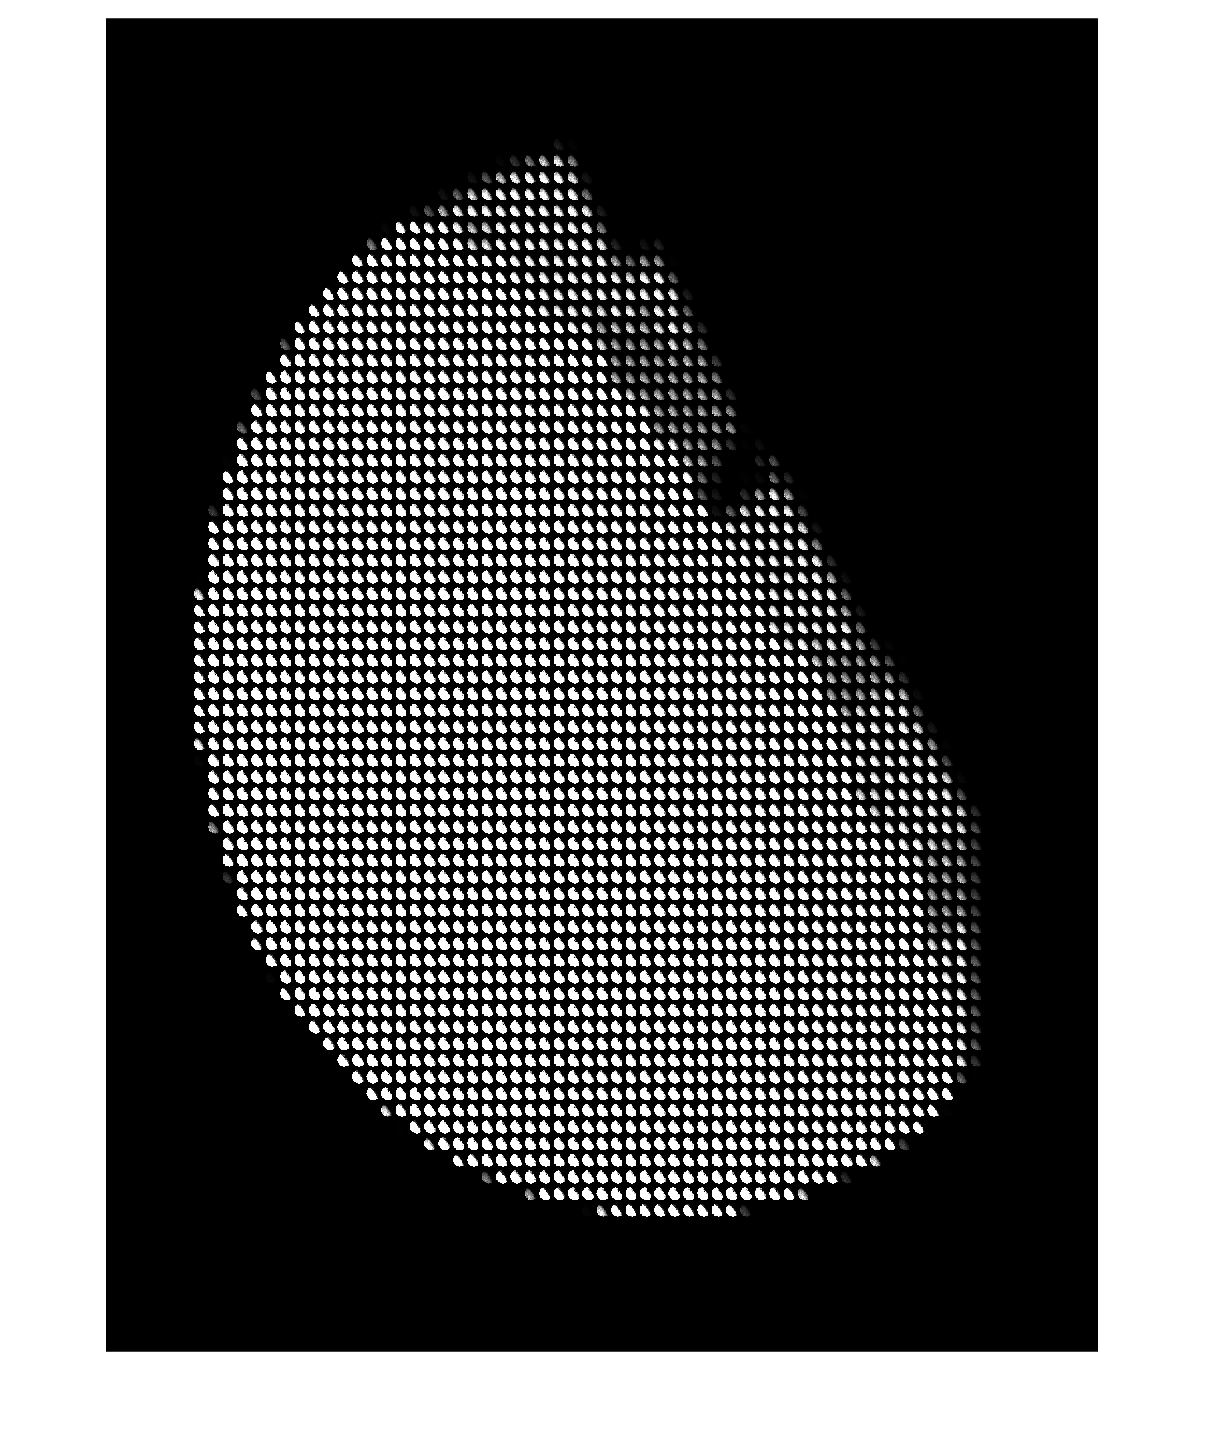

% Transform the mosaic cell array into matrix 
mosaic = cell2mat(cell_mosaic);
imshow(mosaic)